原始数据:
    Tau       Beta  
    ____    ________

    0.01    0.021763
     0.1    0.054413
       1      0.1004
       5     0.11955
      10     0.12032
      15     0.11832
      20     0.11579
      25      0.1144
      50     0.10371
     100    0.090203
     200    0.075069



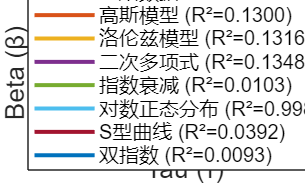


最佳拟合模型: 对数正态分布 (R² = 0.9988)
拟合参数:
    0.1205
    2.0051
    3.4461



所有模型拟合结果:
        Model         R_squared                Parameters            
    ______________    _________    __________________________________

    {'对数正态分布'}      0.99875    {'0.1205, 2.0051, 3.4461'        }
    {'二次多项式' }      0.13484    {'-0.0000, 0.0006, 0.0877'       }
    {'洛伦兹模型' }       0.1316    {'2409.7167, 71.7647, 21664.0462'}
    {'高斯模型'   }      0.13005    {'0.1117, 80.1019, 168.6005'     }
    {'S型曲线'    }     0.039212    {'0.0960, -0.0368, 234.6185'     }
    {'指数衰减'   }     0.010308    {'33.1876, 0.0000, -33.0916'     }
    {'双指数'     }    0.0092983    {'0.0507, 0.0005, 0.0452, 0.0005'}



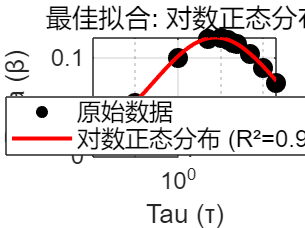

clear;clc;clf;
tau_values=[0.01 0.1 1 5 10 15 20 ...
    25 50 100 200];
base_dir='E:\LungFEM_Study\Results\RawData\tau';
beta_values=get_beta_for_taus(tau_values,base_dir);

原始数据:
    Tau       Beta  
    ____    ________

    0.01    0.021763
     0.1    0.054413
       1      0.1004
       5     0.11955
      10     0.12032
      15     0.11832
      20     0.11579
      25      0.1144
      50     0.10371
     100    0.090203
     200    0.075069




最佳拟合模型: 对数正态分布 (R² = 0.9988)
拟合参数:
    0.1205
    2.0051
    3.4461



所有模型拟合结果:
        Model         R_squared                Parameters            
    ______________    _________    __________________________________

    {'对数正态分布'}      0.99875    {'0.1205, 2.0051, 3.4461'        }
    {'二次多项式' }      0.13484    {'-0.0000, 0.0006, 0.0877'       }
    {'洛伦兹模型' }       0.1316    {'2409.7167, 71.7647, 21664.0462'}
    {'高斯模型'   }      0.13005    {'0.1117, 80.1019, 168.6005'     }
    {'S型曲线'    }     0.039212    {'0.0960, -0.0368, 234.6185'     }
    {'指数衰减'   }     0.010308    {'33.1876, 0.0000, -33.0916'     }
    {'双指数'     }    0.0092983    {'0.0507, 0.0005, 0.0452, 0.0005'}



% 获取不同tau下的beta值
fit_beta_tau_relationship(tau_values, beta_values);